# 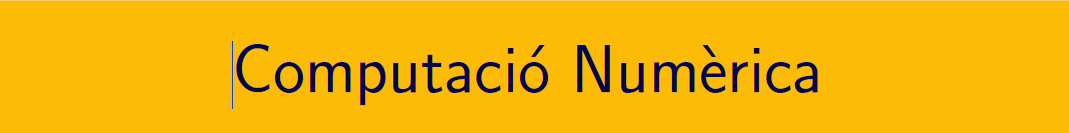

================================================================================

# Pràctica 11. Integració aproximada de funcions i dades (II).

`Document preparat per M. Àngela Grau Gotés - 10 de maig de 2023`

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document .pdf i en el document **CN_exercicis_tema5_2.pdf**, els podeu trobar en el campus virtual. 

### Bloc 4.  Monte Carlo Simulation

Una petita introducció dels mètodes en MATLAB® es pot consultar a l'enllaç següent: [https://es.mathworks.com/discovery/monte-carlo-simulation.html](https://es.mathworks.com/discovery/monte-carlo-simulation.html)

Integració aproximada pel mètode de Montecarlo:  una explicació en el video del professor Craig McNeile a youtube [https://www.youtube.com/watch?v=AaCeUpSFHAk](https://www.youtube.com/watch?v=AaCeUpSFHAk) 

Que s'enten per Monte Carlo Simulation? Una classe del professor John Guttag en el Mit Course: [Introduction to Computational Thinking and Data Science](https://ocw.mit.edu/courses/electrical-engineering-and-computer-science/6-0002-introduction-to-computational-thinking-and-data-science-fall-2016/). Disponible a l'enllaç [https://www.youtube.com/watch?v=OgO1gpXSUzU](https://www.youtube.com/watch?v=OgO1gpXSUzU)

### Bloc 5.  Fórmules d'integració GAUSSIANA

Podeu descarregar els codis de MatLab File Exchange:   

- [Gaussian quadratures for several orthogonal polynomials](https://es.mathworks.com/matlabcentral/fileexchange/48144-gaussian-quadratures-for-several-orthogonal-polynomials) (Chebyshev)

- [Legendre Laguerre and Hermite - Gauss Quadrature](https://es.mathworks.com/matlabcentral/fileexchange/26737-legendre-laguerre-and-hermite-gauss-quadrature?s_tid=prof_contriblnk)

### Integració Gauss-Legendre

La fórmula d'integració és $\displaystyle\int_{-1}^{1} f(x)\,dx=\sum_{j=1}^{m}\beta_i f(x_i)+E_m\{f\}  $ amb els nodes $\mathbf{x_1,\dots,x_m}$ els zeros del polinomi de Legendre de grau $m$ i $\displaystyle  W_j= \displaystyle\int_{-1}^{1} l_j(x)\,dx$ per $l_j(x)$els polinomis interpoladors de Lagrange dels nodes escollits

### Polinomis de Legendre.

    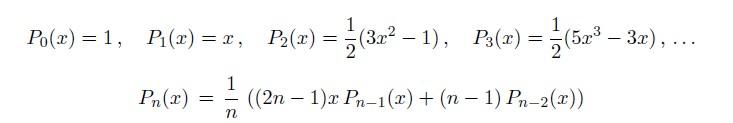

clc,clf,clearvars
m = 3;
[xi, w] = gauss_quad(m,'legen')   % Felipe Uribe, Gaussian quadratures for several orthogonal polynomials 
[x3, w3] = GaussLegendre_2(m)     % Geert Van Damme, Legendre Laguerre and Hermite - Gauss Quadrature

### Integració Gauss-Legendre

La fórmula d'integració és $\displaystyle
\int_{-1}^{1} \frac{g(t)}{\sqrt{1-t^2}}\,dt=\frac{\pi}{m}\sum_{i=1}^{m} g(t_i)+E_m\{g\}$ amb  els nodes $\mathbf{t_i} = \displaystyle\cos\left[ \frac{(2i-1)\pi}{2m}\right],\  i=1,\cdots,m$ els zeros del polinomi de Txebixev de grau $m$.

### Polinomis de Chebyshev

clc,clf,clearvars
m = 3;
[xi,w] = gauss_quad(m,'cheby')

## PRCTIQUEM .....

### Exercici 1. Aplicació dades discretes

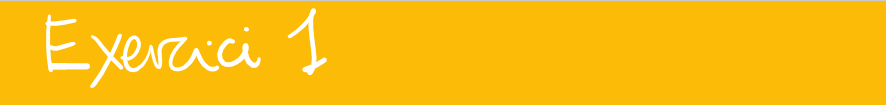

Trobeu la distància que ha recorregut un mòvil a partit de les dades de la següent taula

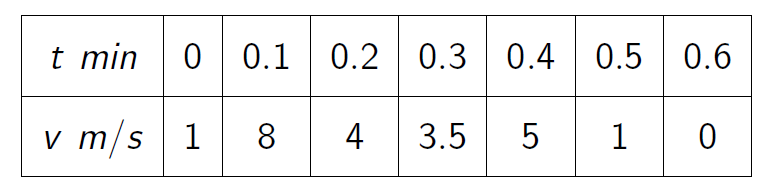

time = linspace(0,0.6,7)*60;
vel = [1 8 4 3.5 5 1 0];

- Representa gràficament les dades de la taula

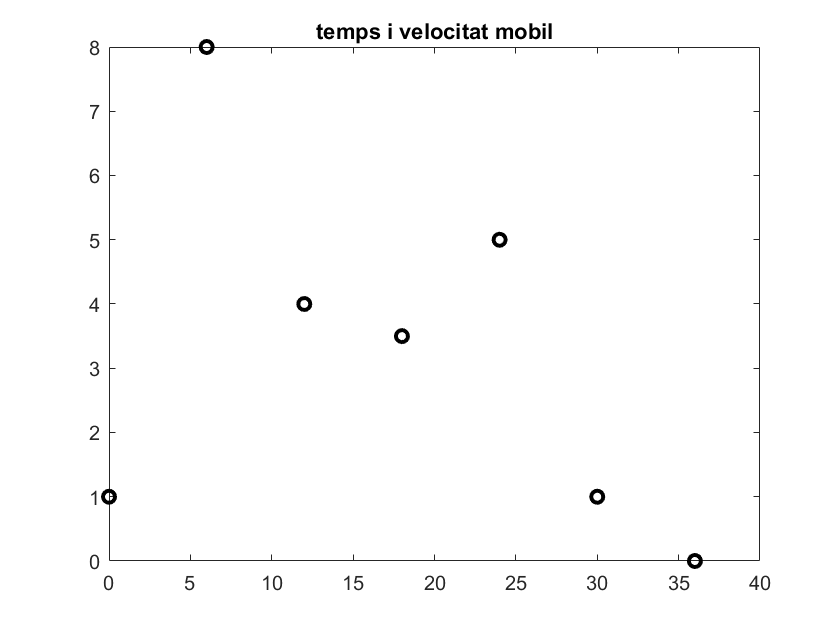

plot(time,vel,'ko', 'LineWidth',2), title('temps i velocitat mobil')

- Explica l'estratègia i dona el resultat pel mètode del punt mig

% lit i = rectangle1 + rectangle2 +  rectangle3 = (t(3)-t(1))*v(2) + ...

- Explica l'estratègia i dona el resultat pel mètode dels trapezis

dT = trapz(time,vel)

dT =      1.320000000000000e+02


- Explica l'estratègia i dona el resultat pel mètode de Simpson

% 
h = (time(3)-time(1))/2

h =    5.999999999999999


H = h/3

H =    2.000000000000000


i = H*(vel(1)+ 4*vel(2) + vel(3)) + H*(vel(3)+ 4*vel(4) + vel(5)) + H*(vel(5)+ 4*vel(6) + vel(7))

i =      1.380000000000000e+02


### Exercici 2. Mètode de Montecarlo

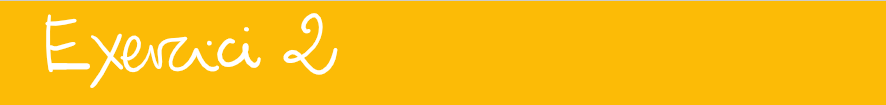

Calculeu els  valors  de    $\displaystyle\int_0^1 x dx = 1/2\,, \quad
\displaystyle\int_0^1 x^2 dx = 1/3\,, \quad
\displaystyle\int_0^4 x dx = 8\,, \quad
\displaystyle\int_{-1}^1 x dx = 1\,.

$

- Tipus I (valor esperat)

% function integral = montecarlo(f, m, a, b)
% f -referencia a la funcio a la que fer l'integral
% m- nombre de llançaments aleatoris
% a- limit inferior
% b- limit superior
% error: de l'ordre de (1/sqrt(m)
m = 10e6;
g = @(x) x;
a = 0; b = 4;
r = rand(1,m)*(b-a) + a;
I = (b-a)*sum(g(r))/m

I =    7.999115355369085


%end

- Tipus II (hit or miss)

f = @(x) x.^2;
a = -1;
b = 1;
m = 10e2;
hmax = max(f(a),f(b));
areaRectangle = (b-a)*hmax;
xr = rand(1,m)*(b-a) + a;
yr = rand(1,m)*hmax;
% plot(xr,yr,'o')
favorables = 0;
for ii = 1:m
    if(yr(ii) < f(xr(ii)))
       favorables = favorables + 1;
    end
end

I = areaRectangle*favorables/m

I =    0.624000000000000


% Ireal = integral(f,a,b)

Ireal =    0.666666666666667


### Exercici 3. Mètode de Montecarlo

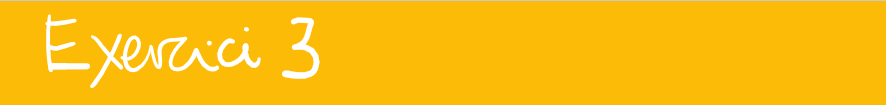

Calculeu el valor de    $\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$ 

- Tipus I (valor esperat)

- Tipus II (hit or miss)

### Exercici 4. Gauss Legendre

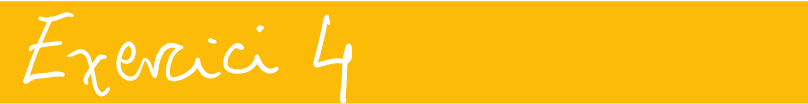

Calcular $\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$

- Valor exacte

clearvars
f = @(x) exp(-0.5*x.^2)

- Fórmula de dos punts: m=2

m = 3
[x w] = GaussLegendre_2(m)

f = function_handle with value:
    @(x)exp(-0.5*x.^2)


I = sum(w.*f(x))

- Fórmula de tres punts: m=3

m =      3


- Fórmula de quatre punts: m=4

x =         -0.774596669241484
                         0
         0.774596669241483


w =          0.555555555555556
         0.888888888888889
         0.555555555555556


- Fórmula de cinc punts: m=5

I =           1.71202024520191


### Exercici 5. Gauss Chebyshev

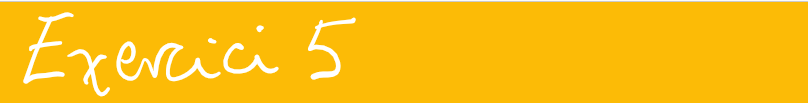

Calculeu el valor de    $$\quad\displaystyle  \int_{-1}^{1}\frac{\cos(\pi x)}{\sqrt{1-x^2}}dx $$ 

- Valor exacte

clc; clear variables; format compact;
format longG;


- Fórmula de dos punts: m=2. Compareu el valor calculat per trapezis (1interval=dos punts)

- Fórmula de tres punts: m=3.  Compareu el valor calculat per Simpson (1interval=tres punts)

- Fórmula de quatre punts: m=4

- Fórmula de cinc punts: m=5

### Exercici 6. Canvi interval

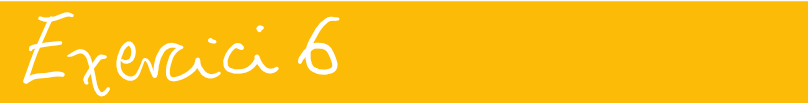

 Calculeu el valor de $  I=\displaystyle\int_{1}^{2} \ln(x)\,dx $ fent ús de fórmules de Gauss-Legendre. Obseveu que el canvi d'interval és $  I=\displaystyle\int_{1}^{2} \ln(x)\,dx = \frac{1}{2}\int_{-1}^{1} \ln\Big(\frac{t+3}{2}\Big)\,dt \,.$

## AUTOAVALUACIÓ ....

#### Fórmules de Newton-Côtes compostes. Mètode Romberg.

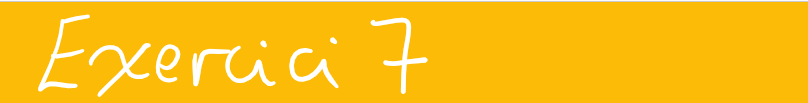

Bajarse el código de [romberg.m](http://www.math.mcgill.ca/gantumur/math578f09/matlab/romberg.m)

            
$$\displaystyle \int_{-1}^1 e^\frac{-x^2}{2} dx\ \approx\  { 1.71124878378430\pm 0.510^{-14}}$$


- Valor exacte

clearvars
format shortG
a=-1; b=1; 
f = @(x)exp(-x.^2/2);

- Mètode del punt mig, h=1,1/2,1/4,1/8,1/16. Exercici per verificar que P(h), P(h/2) ...  millora l'aproximació

- Mètode dels trapezis, h=1,1/2,1/4,1/8,1/16. Exercici per verificar que T(h), T(h/2) ...  millora l'aproximació

- Regla de Simpson, h=1,1/2,1/4,1/8. Exercici per verificar que S(h), S(h/2) ...  millora l'aproximació

- Mètode de Romberg, h=1,1/2,1/4,1/8,1/16

- Fórmula de Gauss-Legendre dos punts: m=2. Compareu el valor calculat per trapezis (1interval=dos punts)

- Fórmula de Gauss-Legendre de tres punts: m=3.  Compareu el valor calculat per Simpson (1interval=tres punts)

- Fórmula de Gauss-Legendre de quatre punts: m=4

- Fórmula de Gauss-Legendre de cinc punts: m=5

`Document preparat per M. Àngela Grau Gotés - 10 de maig de 2023`

% Codis de les funcions 

function y=fun(x)
y=sin(x)./x;
if isnan(y)
    y=1;
end
end